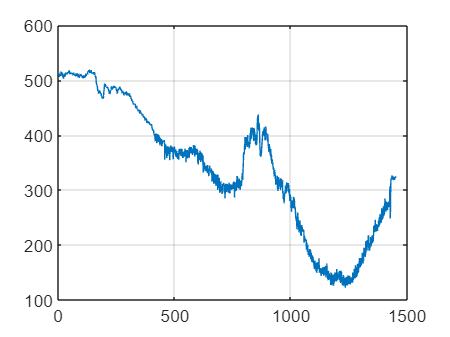

load leleccum; 
indx = 2000:3450;
x = leleccum(indx);
plot(x)
grid on;

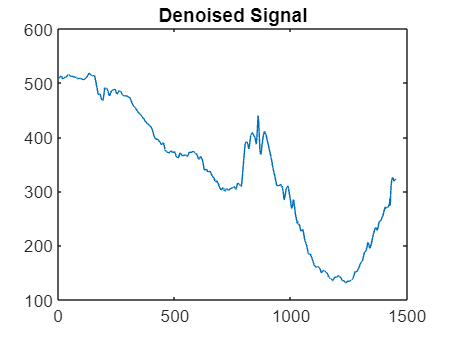

[SIGDEN,~,thrParams,~,BestNbOfInt] = cmddenoise(x,'sym4',3);
plot(SIGDEN)
title('Denoised Signal')

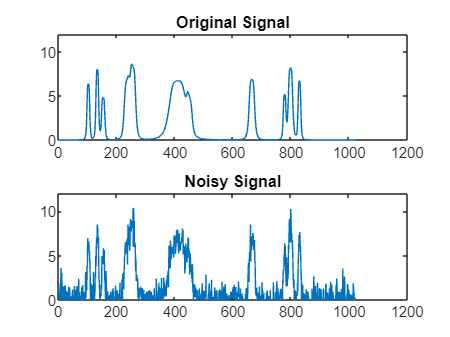

rng default;
[X,XN] = wnoise('bumps',10,sqrt(6));
subplot(211)
plot(X); title('Original Signal');
AX = gca;
AX.YLim = [0 12];
subplot(212)
plot(XN); title('Noisy Signal');
AX = gca;
AX.YLim = [0 12];

xdMODWT = wden(XN,'modwtsqtwolog','s','mln',3,'db2');
xdMODWT1 = wden(XN,'modwtsqtwolog','s','mln',2,'sym2');
e=mean((X-xdMODWT).^2) 

e = 0.1380

e2=mean((X-xdMODWT1).^2)

e2 = 0.2196

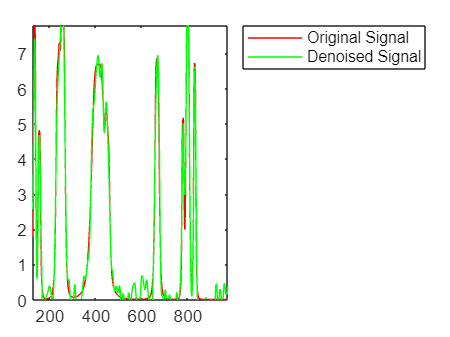

figure;
plot(X,'r')
hold on;
plot(xdMODWT,'g')
legend('Original Signal','Denoised Signal','Location','NorthEastOutside')
axis tight;
hold off;

xlim([127 973])
ylim([0.0 7.8])